s_ix = SessManager.special_sessions_usable_index('Mouse2022');
sm = SessManager;
s_info = sm.cons_usable(s_ix, true);
d_raw = DecodeTensor(s_info, 'rawTraces');

Total trials: 371	Throwing away 0	keeping 371


d_deconv = DecodeTensor(s_info, 'spikeDeconvTrace');

Total trials: 371	Throwing away 0	keeping 371


d_dc = DecodeTensor(s_info, 'spikeDeconv');

Total trials: 371	Throwing away 0	keeping 371


d_events = DecodeTensor(s_info, 'IED');

Total trials: 371	Throwing away 0	keeping 371


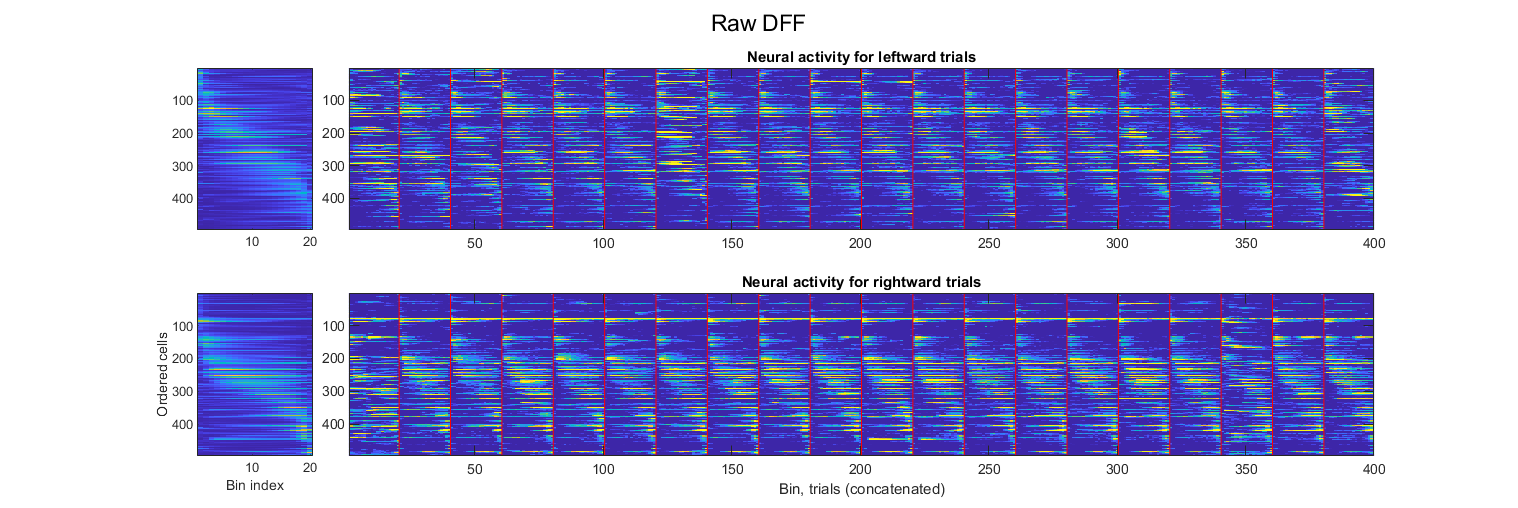

figure('Units', 'inches', 'Position', [11.4741    8.0690   13.0862    4.3793]);
d_raw.vis(@(x) max(0,min(1,x)));
sgtitle('Raw DFF');

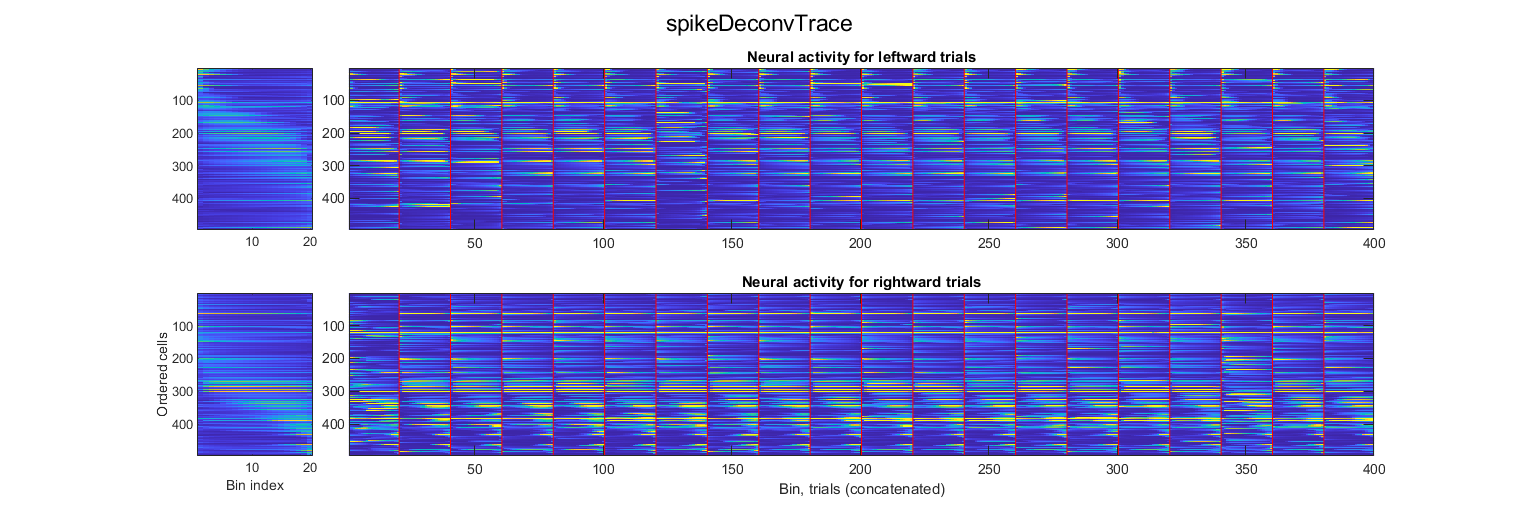

figure('Units', 'inches', 'Position', [11.4741    8.0690   13.0862    4.3793]);
d_deconv.vis(@(x) max(0,min(1,x)));
sgtitle('spikeDeconvTrace');

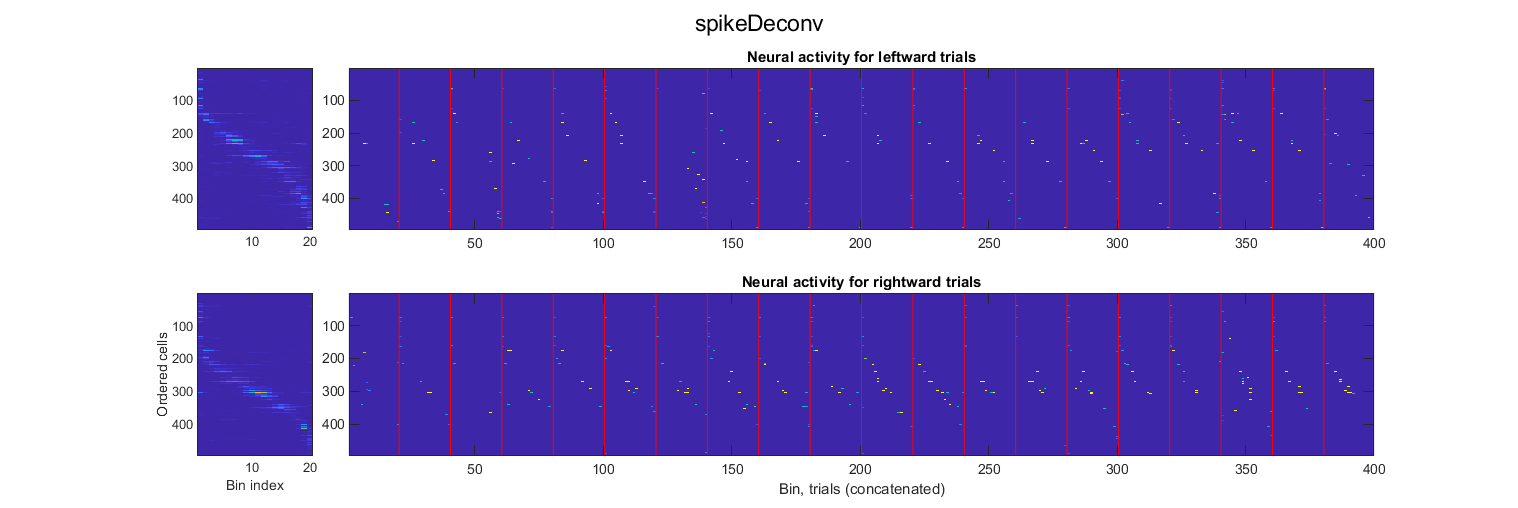

figure('Units', 'inches', 'Position', [11.4741    8.0690   13.0862    4.3793]);
d_dc.vis(@(x) max(0,min(1,x)));
sgtitle('spikeDeconv');

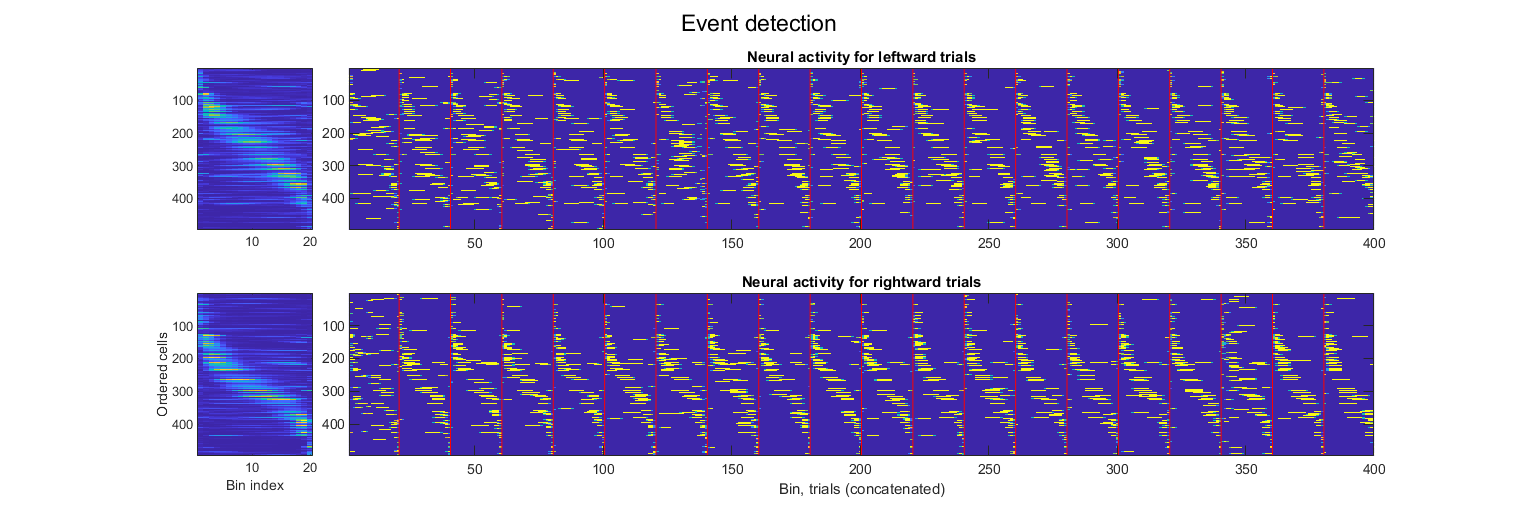

figure('Units', 'inches', 'Position', [11.4741    8.0690   13.0862    4.3793]);
d_events.vis(@(x) max(0,min(1,x)));
sgtitle('Event detection');

load(d_raw.source_path);
tr_raw = tracesEvents.rawTraces;
tr_deconv = tracesEvents.spikeDeconvTrace;
tr_dc = tracesEvents.spikeDeconv;
tr_events = iterative_event_detection(tr_raw);

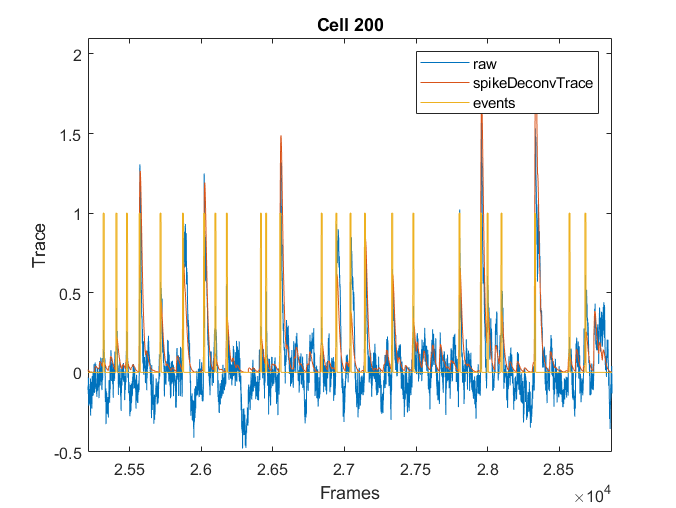

n_ix = 200;
figure;
plot(tr_raw(:,n_ix));
hold on;
plot(tr_deconv(:,n_ix));
plot(tr_events(:,n_ix));
legend raw spikeDeconvTrace events
xlabel Frames
ylabel Trace
title(sprintf('Cell %d', n_ix));

xlim([25210 28868])
ylim([-0.50 2.10])

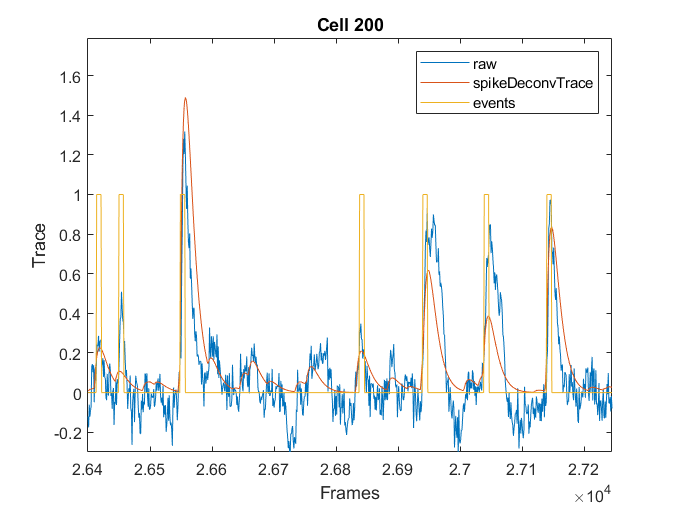



figure;
plot(tr_raw(:,n_ix));
hold on;
plot(tr_deconv(:,n_ix));
plot(tr_events(:,n_ix));
legend raw spikeDeconvTrace events
xlabel Frames
ylabel Trace
title(sprintf('Cell %d', n_ix));

xlim([26400 27245])
ylim([-0.30 1.79])

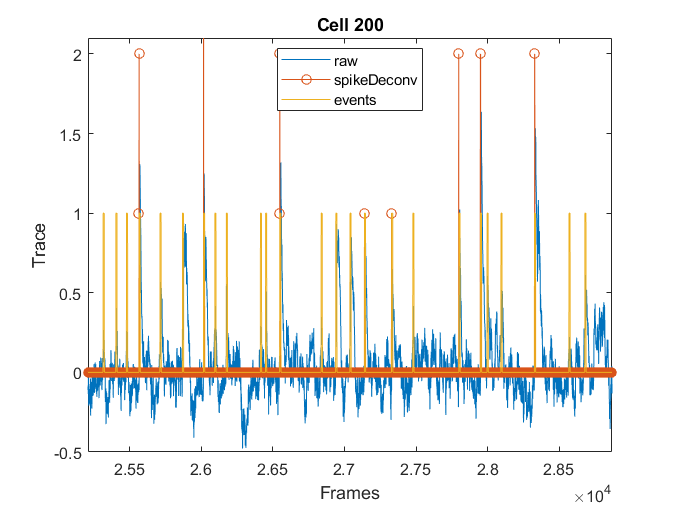

figure;
plot(tr_raw(:,n_ix));
hold on;
plot(tr_dc(:,n_ix), '-o');
plot(tr_events(:,n_ix));
legend raw spikeDeconv events
legend Location best
xlabel Frames
ylabel Trace
title(sprintf('Cell %d', n_ix));

xlim([25210 28868])
ylim([-0.50 2.10])

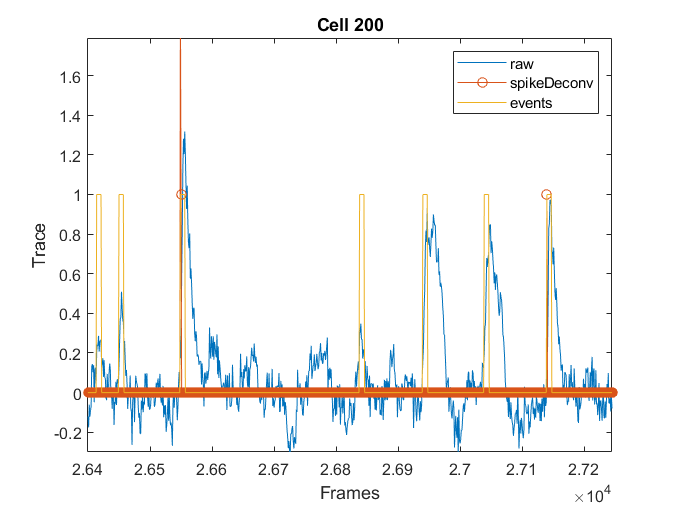



figure;
plot(tr_raw(:,n_ix));
hold on;
plot(tr_dc(:,n_ix), '-o');
plot(tr_events(:,n_ix));
legend raw spikeDeconv events
xlabel Frames
ylabel Trace
title(sprintf('Cell %d', n_ix));

xlim([26400 27245])
ylim([-0.30 1.79])